T1 数值解

fun=@(x,y)x.*exp(y);
ymax=@(x)x;
I=integral2(fun,0,1,0,ymax);
disp(I)

    0.5000



符号解

syms x y;
f=x*exp(y);
P=int(int(f,y,0,x),x,0,1);
disp(P)

$$\frac{1}{2}$$

T2 数值解

% 定义方程组函数
func = @(vars) [vars(1)^2 + 3*vars(2) + 1; 
                vars(2)^2 + 4*vars(1) + 1];

% 设置初始点
initial_guess = [0; 0];

% 使用fsolve求解
options = optimoptions('fsolve', 'Display', 'off');  % 关闭迭代显示
solution = fsolve(func, initial_guess, options);

% 显示结果
fprintf('数值解: x = %.6f, y = %.6f\n', solution(1), solution(2));

数值解: x = -0.282384, y = -0.359914


符号解

clear;clc;
syms x y

eq1 = x^2 + 3*y + 1 == 0;
eq2 = y^2 + 4*x + 1 == 0;

[x,y] = solve([eq1, eq2], [x, y]);

disp('符号解为：');

符号解为：


disp(x);

$$\begin{array}{l} \left(\begin{array}{c} -\frac{{\mathrm{root}\left(\sigma_{1},z,1\right)}^{2}}{4}-\frac{1}{4}\\ -\frac{{\mathrm{root}\left(\sigma_{1},z,2\right)}^{2}}{4}-\frac{1}{4}\\ -\frac{{\mathrm{root}\left(\sigma_{1},z,3\right)}^{2}}{4}-\frac{1}{4}\\ -\frac{{\mathrm{root}\left(\sigma_{1},z,4\right)}^{2}}{4}-\frac{1}{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}+2\,z^{2}+48\,z+17 \end{array}$$

disp(y);

$$\left(\begin{array}{c} \mathrm{root}\left(z^{4}+2\,z^{2}+48\,z+17,z,1\right)\\ \mathrm{root}\left(z^{4}+2\,z^{2}+48\,z+17,z,2\right)\\ \mathrm{root}\left(z^{4}+2\,z^{2}+48\,z+17,z,3\right)\\ \mathrm{root}\left(z^{4}+2\,z^{2}+48\,z+17,z,4\right) \end{array}\right)$$

T3 数值解

odefun = @(x, y) [y(2); -2*x*y(2)^2];

xspan = [0, 5];  % 积分区间
y0 = [1; -0.5];  % 初始条件: y(0)=1, y'(0)=-1/2

[xsol, ysol] = ode45(odefun, xspan, y0);

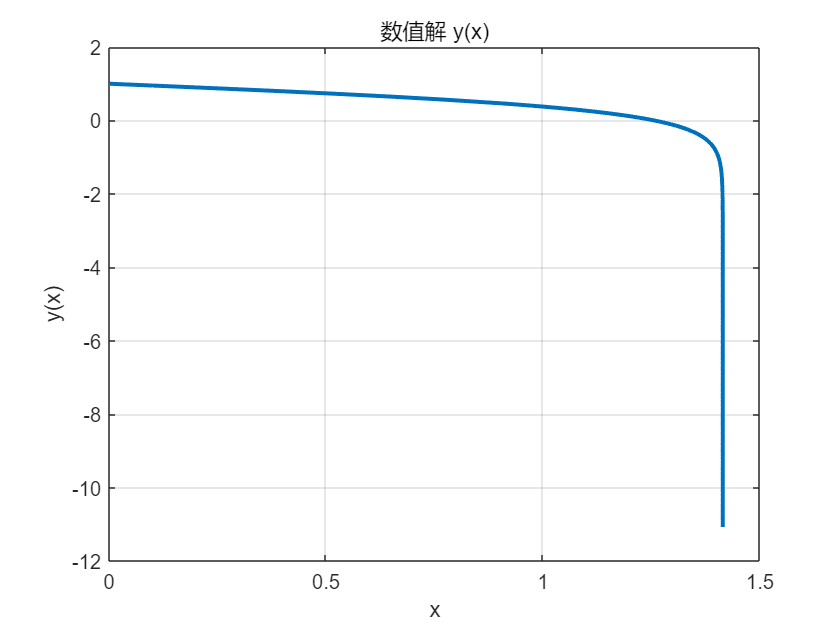


plot(xsol, ysol(:,1), 'LineWidth', 2);
xlabel('x'); ylabel('y(x)');
title('数值解 y(x)');
grid on;

符号解

syms y(x)

Dy = diff(y, x);
D2y = diff(y, x, 2);

% 定义方程和初始条件
ode = D2y + 2*x*(Dy)^2 == 0;
cond1 = y(0) == 1;
cond2 = Dy(0) == -1/2;

% 解微分方程
ySol = dsolve(ode, [cond1, cond2]);

disp('符号解为：');

符号解为：


disp(ySol);

$$1-\frac{\sqrt{2}\,\mathrm{atanh}\left(\frac{\sqrt{2}\,x}{2}\right)}{2}$$

T4 

% 目标函数
f = @(x) x(1)^2 + x(2)*x(3);

% 线性不等式约束 A*x <= b
A = [1 2 -1; 2 1 0];
b = [5; 3];

% 初始点
x0 = [1 1 1];

% 下界
lb = [0 0 0];

% 求解
x_opt = fmincon(f, x0, A, b, [], [], lb, []);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



disp('最优解 x =');

最优解 x =


disp(x_opt);

    0.2025    0.1778    0.3341



disp('最小值 f(x) =');

最小值 f(x) =


disp(f(x_opt));

    0.1004



T5 fsurf

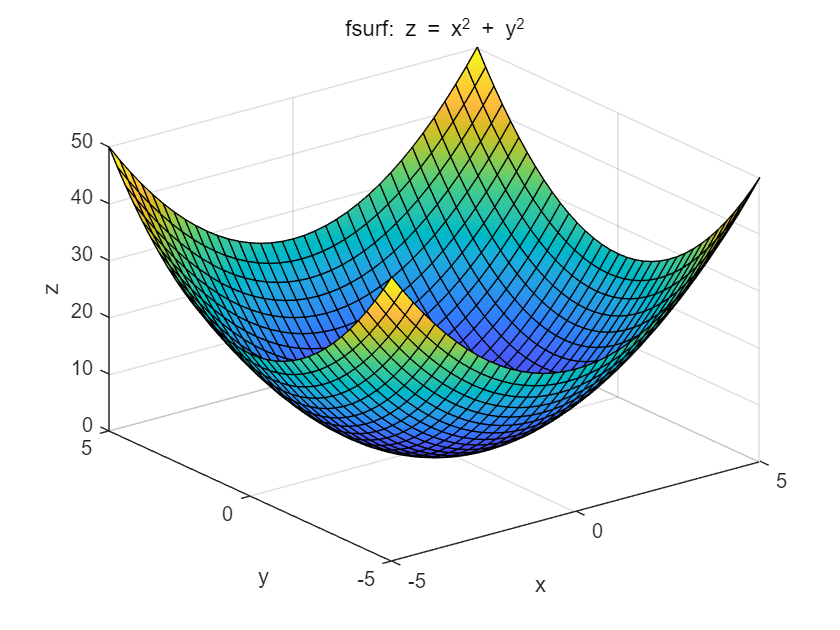

fsurf(@(x,y) x.^2 + y.^2, [-5 5 -5 5]);
title('fsurf: z = x^2 + y^2');
xlabel('x'); ylabel('y'); zlabel('z');

fimplicit

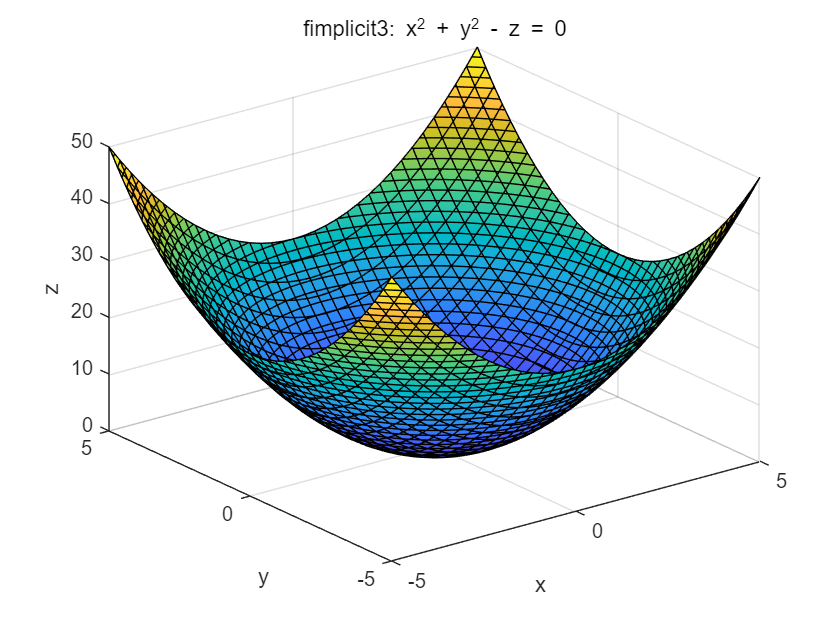

fimplicit3(@(x,y,z) x.^2 + y.^2 - z, [-5 5 -5 5 0 50]);
title('fimplicit3: x^2 + y^2 - z = 0');
xlabel('x'); ylabel('y'); zlabel('z');

T6 5次多项式拟合

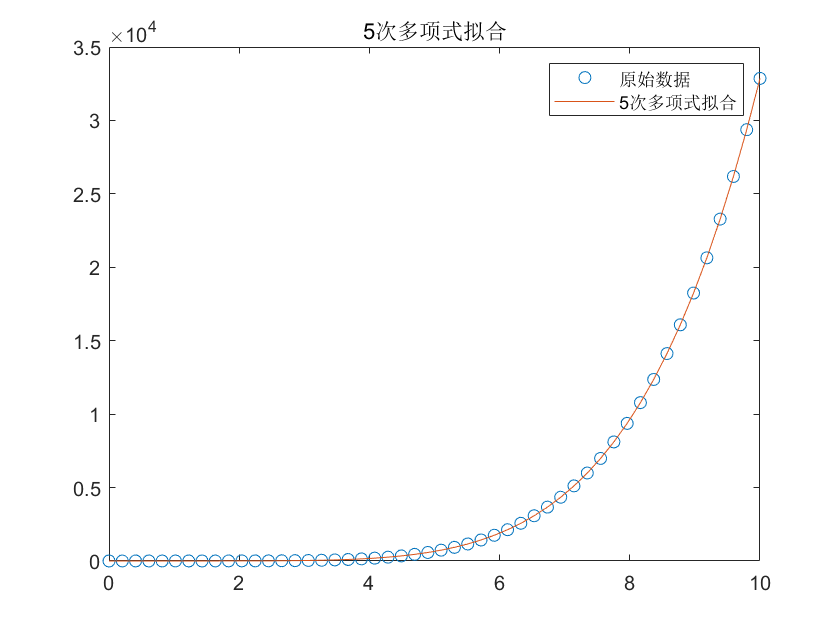

% 生成测试数据（可以不写）
rng(42);
X = linspace(0, 10, 50)';
Y = 0.5*X.^5 - 2*X.^4 + 3*X.^3 - 1.5*X.^2 + 0.8*X + 2; % 5次多项式函数

% 使用5次多项式拟合
p = polyfit(X, Y, 5);
Y_fit = polyval(p, X);

plot(X, Y, 'o', X, Y_fit, '-');
legend('原始数据', '5次多项式拟合');
title('5次多项式拟合');

指数拟合

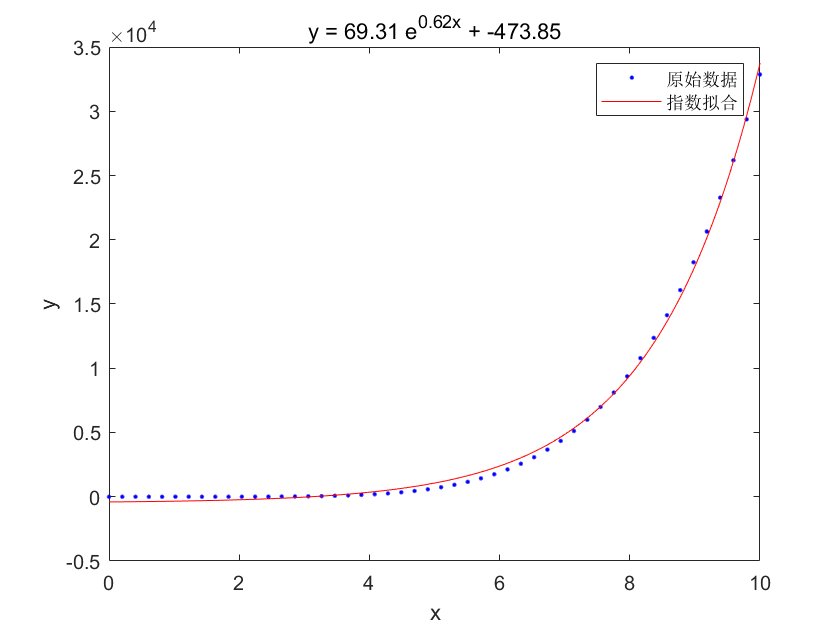

% 定义指数模型
ft = fittype('a*exp(b*x) + c', 'independent', 'x');

% 设置初始点
startPoints = [1, 0.1, 0];

% 执行拟合
[fitresult, gof] = fit(X, Y, ft, 'StartPoint', startPoints);

% 获取参数
a = fitresult.a;
b = fitresult.b;
c = fitresult.c;

% 绘图对比
plot(fitresult, X, Y);
legend('原始数据', '指数拟合');
title(sprintf('y = %.2f e^{%.2fx} + %.2f', a, b, c));

T7 参数方程法

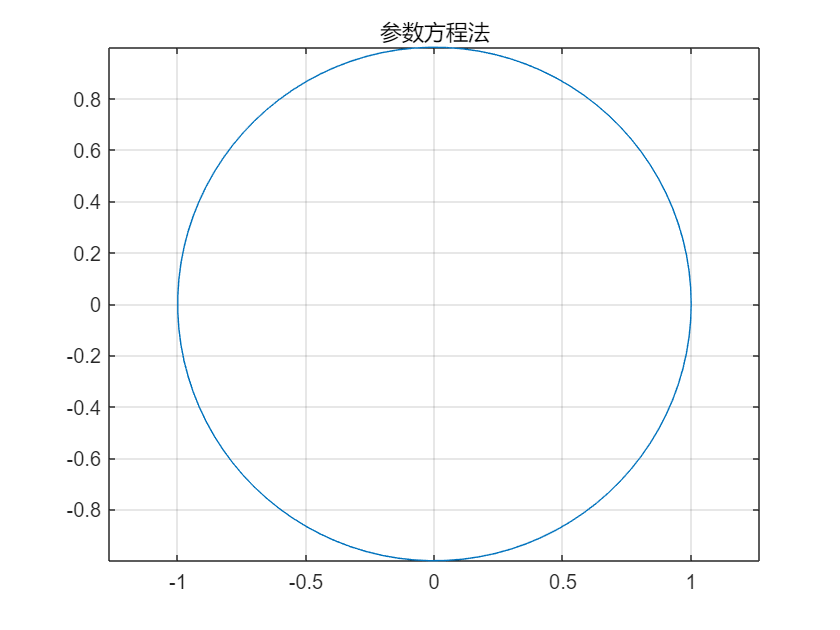

theta = linspace(0, 2*pi, 100);
x = cos(theta);
y = sin(theta);
plot(x, y);
axis equal; title('参数方程法');
grid on;

隐函数法

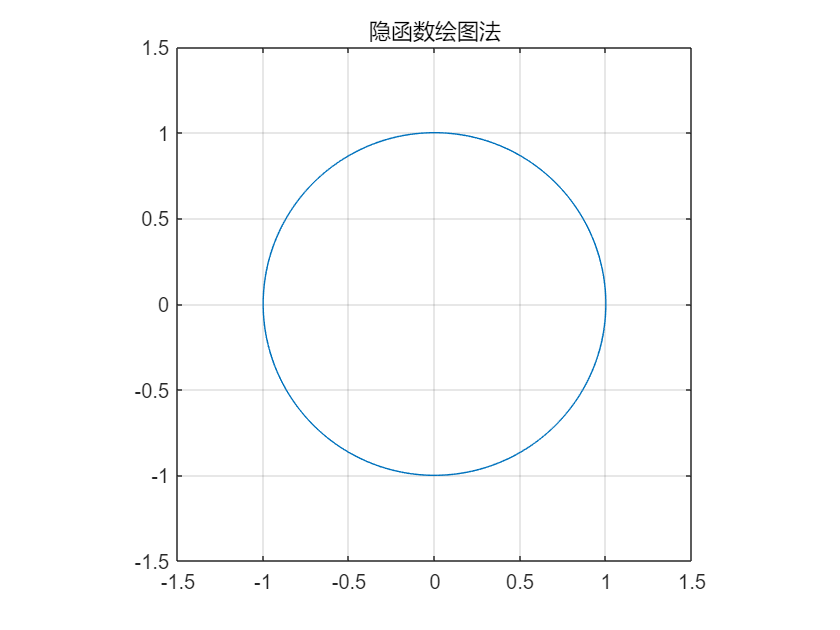

fimplicit(@(x,y) x.^2 + y.^2 - 1, [-1.5 1.5 -1.5 1.5]);
axis equal; title('隐函数绘图法'); grid on;